# 360全景透视与环形鱼眼图像顺滑过渡算法

author:崔星星

date:2024.9

为了在APP中较顺滑的在“透视”和”环形鱼眼“两种视角平滑过渡，数学上表现为单位球体内，外之间视角变换，不能简单的对各个变量进行线性插值(仅适用球体内的”小行星“和”透视“之间的模式)，示意图如下：

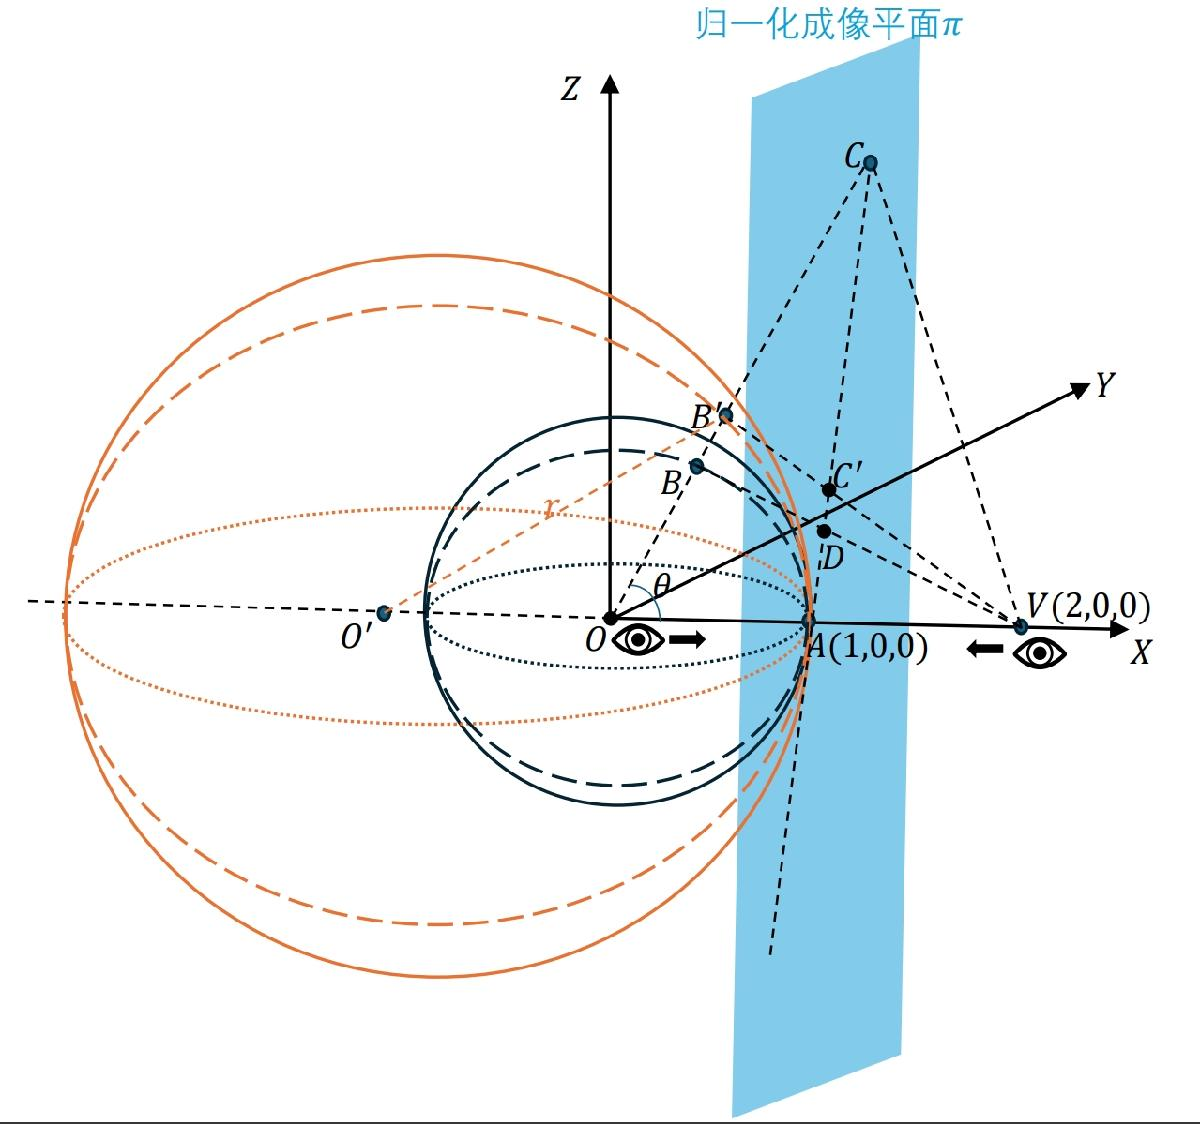

syms r l theta
assume(theta>=0&theta<90)

assumptions

$$ans = \left(\begin{array}{cc} \theta <90 & 0\leq \theta \end{array}\right)$$

equ1 = r.^2==(r-1).^2+l.^2-2*l*(r-1).*cos(pi-theta)

$$equ1 = r^{2}={\left(r-1\right)}^{2}+l^{2}+2\,l\,\cos\left(\theta \right)\,\left(r-1\right)$$


sol1 = solve(equ1,l)

$$sol1 = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta \right)+\sigma_{1}-r\,\cos\left(\theta \right)\\ \cos\left(\theta \right)-\sigma_{1}-r\,\cos\left(\theta \right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{r^{2}\,{\cos\left(\theta \right)}^{2}-2\,r\,{\cos\left(\theta \right)}^{2}+2\,r+{\cos\left(\theta \right)}^{2}-1} \end{array}$$